% global FixPeakChannel peak_point_define
% FixPeakChannel=0;
% peak_point_define=42;

cd('/Volumes/PcSSDA/1626/20220313_1626_SW_002')
ExperimentName='20220313_1626_SW_002'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[11 12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     11    12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_202200403.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end


analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220313_1626_SW_002FLIM001.mat'
     folder: '/Volumes/PcSSDA/20220313_1626_SW_002'
       date: '13-Mar-2022 16:34:48'
      bytes: 2982
      isdir: 0
    datenum: 7.3859e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_202200403.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end


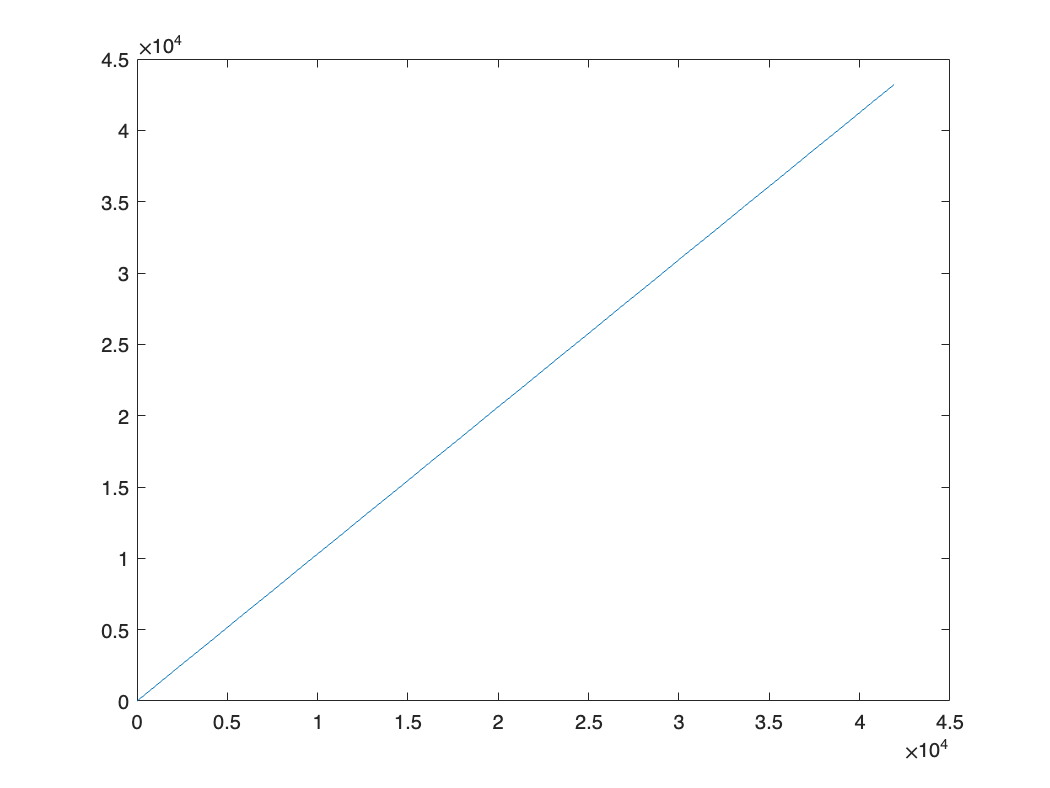

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_DC_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_DC_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)


% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['extracted_data/StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end


states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_202200403.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);



mkdir([analysis_name,'csv_20220426'])

csv_name=[analysis_name,'csv_20220426/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_DC_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_DC_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)


save('FLP_analysis_0426.mat')

cd('/Volumes/PcSSDA/1626/20220313_1626_SW_002')
load('FLP_analysis_0426.mat')

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_1_intensity=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    median_1_intensity=[median_1_intensity median(this_epoch_intensity)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];
end

median_time_2=[];
median_2=[];
median_2_intensity=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    median_2_intensity=[median_2_intensity median(this_epoch_intensity)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
end

median_time_3=[];
median_3=[];
median_3_intensity=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    median_3_intensity=[median_3_intensity median(this_epoch_intensity)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
end

median_time_4=[];
median_4=[];
median_4_intensity=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    median_4_intensity=[median_4_intensity median(this_epoch_intensity)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
end

% global FixPeakChannel peak_point_define
% FixPeakChannel=1;
% peak_point_define=42;
cd('/Volumes/PcSSDA/1626/20220318_1626_SW_003')
ExperimentName='20220318_1626_SW_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7; % What's the acquisition number of the first offical recording
number_of_acq = 22; % How many chunks of recordings are there?
Dark_hours=[7 8 9 10 11 12 13 14 15 16 17 18]

Dark_hours =      7     8     9    10    11    12    13    14    15    16    17    18


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220403.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220318_1626_SW_003FLIM001.mat'
     folder: '/Volumes/PcSSDA/20220318_1626_SW_003'
       date: '18-Mar-2022 18:49:20'
      bytes: 2880
      isdir: 0
    datenum: 7.385987842592592e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220403.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end


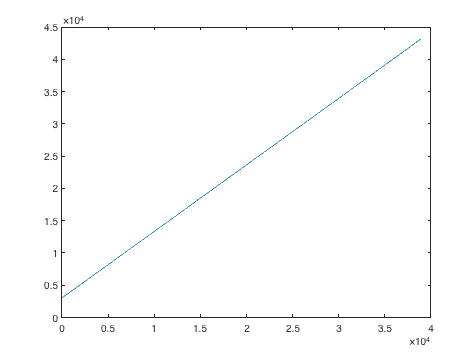

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_DC_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_DC_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)


% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['extracted_data/StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end


states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220403.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);



mkdir([analysis_name,'csv_20220426'])

csv_name=[analysis_name,'csv_20220426/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_DC_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_DC_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)


save('FLP_analysis_0426.mat')

cd('/Volumes/PcSSDA/1626/20220318_1626_SW_003')
load('FLP_analysis_0426.mat')

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_1_intensity=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    median_1_intensity=[median_1_intensity median(this_epoch_intensity)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];
end

median_time_2=[];
median_2=[];
median_2_intensity=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    median_2_intensity=[median_2_intensity median(this_epoch_intensity)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
end

median_time_3=[];
median_3=[];
median_3_intensity=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    median_3_intensity=[median_3_intensity median(this_epoch_intensity)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
end

median_time_4=[];
median_4=[];
median_4_intensity=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    median_4_intensity=[median_4_intensity median(this_epoch_intensity)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
end

cd('/Volumes/PcSSDA/1626/20220329_1626_SW_004')
ExperimentName='20220329_1626_SW_004'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 17; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220403.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220329_1626_SW_004FLIM001.mat'
     folder: '/Volumes/PcSSDA/20220329_1626_SW_004'
       date: '29-Mar-2022 17:44:38'
      bytes: 3039
      isdir: 0
    datenum: 7.386097393287037e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220403.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end


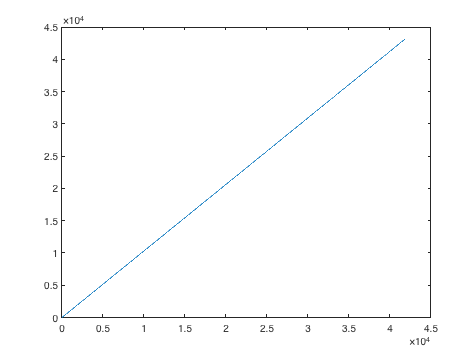

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_DC_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_DC_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)


% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['extracted_data/StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end


states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220403.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);



mkdir([analysis_name,'csv_20220426'])

csv_name=[analysis_name,'csv_20220426/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_DC_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_DC_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)


save('FLP_analysis_0426.mat')

cd('/Volumes/PcSSDA/1626/20220329_1626_SW_004')
load('FLP_analysis_0426.mat')

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_1_intensity=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    median_1_intensity=[median_1_intensity median(this_epoch_intensity)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];
end

median_time_2=[];
median_2=[];
median_2_intensity=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    median_2_intensity=[median_2_intensity median(this_epoch_intensity)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
end

median_time_3=[];
median_3=[];
median_3_intensity=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    median_3_intensity=[median_3_intensity median(this_epoch_intensity)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
end

median_time_4=[];
median_4=[];
median_4_intensity=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    this_epoch_intensity=intensity_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    median_4_intensity=[median_4_intensity median(this_epoch_intensity)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
end


t=time_z_all_darkonly;
t1=t(median_time_1);
t2=t(median_time_2);
t3=t(median_time_3);
t4=t(median_time_4);

for i=1:12
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    
    this_plot_median_points_1=median_time_1(find(t1>=3600*(i-1) & t1<=3600*i));
    this_plot_median_points_2=median_time_2(find(t2>=3600*(i-1) & t2<=3600*i));
    this_plot_median_points_3=median_time_3(find(t3>=3600*(i-1) & t3<=3600*i));
    this_plot_median_points_4=median_time_4(find(t4>=3600*(i-1) & t4<=3600*i));
    
    figure
    yyaxis left
    imagesc(states_for_time_all_dark(this_plot_points)')
    caxis([1 4])
    colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
    colorbar
    set(gca, 'YTick', []);
    title(['empirical lifetime ',num2str(i),' hour' ])
    
    yyaxis right
    plot(tau_empTrunc_all_darkonly(this_plot_points),'LineWidth',2,'Color','white')
    
    
    hold on
    yyaxis right
    plot(this_plot_median_points_1-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_2-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_3-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3)','o','MarkerSize',10,'MarkerFaceColor','Green')
    plot(this_plot_median_points_4-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4)','o','MarkerSize',10,'MarkerFaceColor','Green')
    hold off
    
    
    
    
    
    
end


save([analysis_name,'_20220314.mat'])